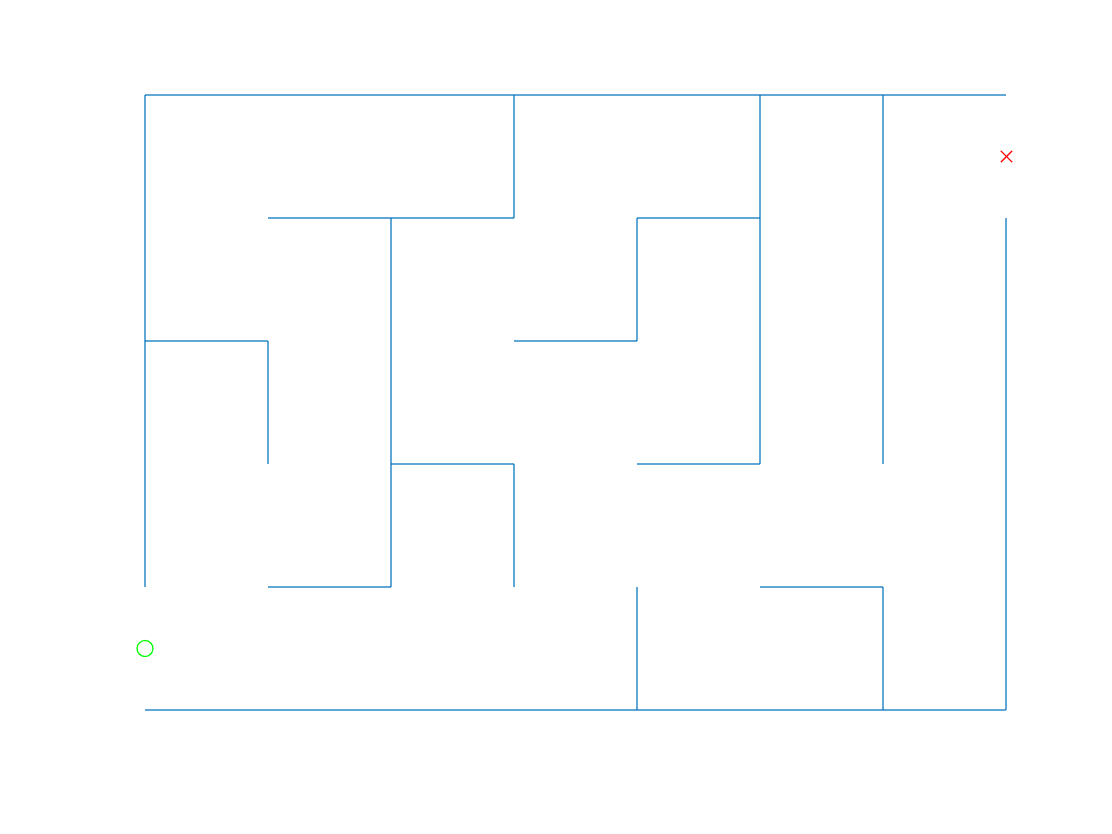

% ======
% ROB521_assignment1.m
% ======
%
% This assignment will introduce you to the idea of motion planning for  
% holonomic robots that can move in any direction and change direction of 
% motion instantaneously.  Although unrealistic, it can work quite well for
% complex large scale planning.  You will generate mazes to plan through 
% and employ the PRM algorithm presented in lecture as well as any 
% variations you can invent in the later sections.
% 
% There are three questions to complete (5 marks each):
%
%    Question 1: implement the PRM algorithm to construct a graph
%    connecting start to finish nodes.
%    Question 2: find the shortest path over the graph by implementing the
%    Dijkstra's or A* algorithm.
%    Question 3: identify sampling, connection or collision checking 
%    strategies that can reduce runtime for mazes.
%
% Fill in the required sections of this script with your code, run it to
% generate the requested plots, then paste the plots into a short report
% that includes a few comments about what you've observed.  Append your
% version of this script to the report.  Hand in the report as a PDF file.
%
% requires: basic Matlab, 
%
% S L Waslander, January 2022
%
clear; close all; clc;

% set random seed for repeatability if desired
%rng(1);

% ==========================
% Maze Generation
% ==========================
%
% The maze function returns a map object with all of the edges in the maze.
% Each row of the map structure draws a single line of the maze.  The
% function returns the lines with coordinates [x1 y1 x2 y2].
% Bottom left corner of maze is [0.5 0.5], 
% Top right corner is [col+0.5 row+0.5]
%

row = 5; % Maze rows
col = 7; % Maze columns
map = maze(row,col); % Creates the maze
start = [0.5, 1.0]; % Start at the bottom left
finish = [col+0.5, row]; % Finish at the top right

h = figure(1);clf; hold on;
plot(start(1), start(2),'go')
plot(finish(1), finish(2),'rx')
show_maze(map,row,col,h); % Draws the maze

drawnow;




% ======================================================
% Question 1: construct a PRM connecting start and finish
% ======================================================
%
% Using 500 samples, construct a PRM graph whose milestones stay at least 
% 0.1 units away from all walls, using the MinDist2Edges function provided for 
% collision detection.  Use a nearest neighbour connection strategy and the 
% CheckCollision function provided for collision checking, and find an 
% appropriate number of connections to ensure a connection from  start to 
% finish with high probability.


% variables to store PRM components
nS = 500;  % number of samples to try for milestone creation
milestones = [start; finish];  % each row is a point [x y] in feasible space
edges = [];  % each row is should be an edge of the form [x1 y1 x2 y2]

disp("Time to create PRM graph")

Time to create PRM graph


tic;
% ------insert your PRM generation code here-------
% Define the minimum distance between edges and walls
minDist = 0.1;

% Loop over number of samples
for i = 2:nS
    % Generate random sample
    x = rand(1) * col + 0.5;
    y = rand(1) * row + 0.5;
    sample = [x, y];
    
    % Check if sample is not too close to walls
    if MinDist2Edges(sample, map)
        % Add sample to milestones
        milestones = [milestones; sample];
        
        % Find the nearest neighbors to the sample
        neighbors = knnsearch(milestones, sample, i-1);
        
        % Connect sample to its nearest neighbors if there is no collision
        for j = 1:length(neighbors)
            neighbor = neighbors(j);
            if ~CheckCollision(map, sample, milestones(neighbor,:))
                edges = [edges; sample milestones(neighbor,:)];
            end
        end
    end
end

P =     5.5343    1.1148


'knnsearch' requires one of the following:
  Statistics and Machine Learning Toolbox
  Text Analytics Toolbox







% ------end of your PRM generation code -------
toc;

figure(1);
plot(milestones(:,1),milestones(:,2),'m.');
if (~isempty(edges))
    line(edges(:,1:2:3)', edges(:,2:2:4)','Color','magenta') % line uses [x1 x2 y1 y2]
end
str = sprintf('Q1 - %d X %d Maze PRM', row, col);
title(str);
drawnow;

print -dpng assignment1_q1.png




% =================================================================
% Question 2: Find the shortest path over the PRM graph
% =================================================================
%
% Using an optimal graph search method (Dijkstra's or A*) , find the 
% shortest path across the graph generated.  Please code your own 
% implementation instead of using any built in functions.

disp('Time to find shortest path');
tic;

% Variable to store shortest path
spath = []; % shortest path, stored as a milestone row index sequence


% ------insert your shortest path finding algorithm here-------




  
 
    
    
% ------end of shortest path finding algorithm------- 
toc;    

% plot the shortest path
figure(1);
for i=1:length(spath)-1
    plot(milestones(spath(i:i+1),1),milestones(spath(i:i+1),2), 'go-', 'LineWidth',3);
end
str = sprintf('Q2 - %d X %d Maze Shortest Path', row, col);
title(str);
drawnow;

print -dpng assingment1_q2.png


% ================================================================
% Question 3: find a faster way
% ================================================================
%
% Modify your milestone generation, edge connection, collision detection 
% and/or shortest path methods to reduce runtime.  What is the largest maze 
% for which you can find a shortest path from start to goal in under 20 
% seconds on your computer? (Anything larger than 40x40 will suffice for 
% full marks)


row = 25;
col = 25;
map = maze(row,col);
start = [0.5, 1.0];
finish = [col+0.5, row];
milestones = [start; finish];  % each row is a point [x y] in feasible space
edges = [];  % each row is should be an edge of the form [x1 y1 x2 y2]

h = figure(2);clf; hold on;
plot(start(1), start(2),'go')
plot(finish(1), finish(2),'rx')
show_maze(map,row,col,h); % Draws the maze
drawnow;

fprintf("Attempting large %d X %d maze... \n", row, col);
tic;        
% ------insert your optimized algorithm here------









% ------end of your optimized algorithm-------
dt = toc;

figure(2); hold on;
plot(milestones(:,1),milestones(:,2),'m.');
if (~isempty(edges))
    line(edges(:,1:2:3)', edges(:,2:2:4)','Color','magenta')
end
if (~isempty(spath))
    for i=1:length(spath)-1
        plot(milestones(spath(i:i+1),1),milestones(spath(i:i+1),2), 'go-', 'LineWidth',3);
    end
end
str = sprintf('Q3 - %d X %d Maze solved in %f seconds', row, col, dt);
title(str);

print -dpng assignment1_q3.png

